# TRIM & LINEARIZATION

## Initialization

clear;
global fi_flag_Simulink
newline = sprintf('\n');

## Flight Conditions

#### Assigned flight condition

fc_afc = struct();
fc_afc.altitude = 10000;
fc_afc.velocity = 350;

#### Accelerometer position analysis

fc_apa = struct()

fc_apa = struct with no fields.


fc_apa.altitude = 15000;
fc_apa.velocity = 500;

## Run Trim

#### Initial guess + setup

FC_flag = 1; % Trim for steady wings-level flight
thrust = 5000;          % thrust, lbs
elevator = -0.09;       % elevator, degrees
alpha = 8.49;              % AOA, degrees
rudder = -0.01;             % rudder angle, degrees
aileron = 0.01;            % aileron, degrees

#### HiFi AFC

disp('Trimming High Fidelity Model AFC:');

Trimming High Fidelity Model AFC:


fi_flag_Simulink = 1;
[trim_state_hi, trim_thrust_hi, trim_control_hi, dLEF, xu_hi] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_afc.velocity, fc_afc.altitude, FC_flag,2);

Trim Values and Cost:
cost   = 7.9921e-06
thrust = 2536.0707 lb
elev   = -3.7245 deg
ail    = 0.10993 deg
rud    = -0.013233 deg
alpha  = 8.6374 deg
dLEF   = 12.6998 deg
Vel.   = 350ft/s


trim_state_lin = trim_state_hi; trim_thrust_lin = trim_thrust_hi; trim_control_lin = trim_control_hi;
operating_point = operpoint('LIN_F16Block');
operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_hi = linearize('LIN_F16Block');
disp(' ');

#### LoFi AFC

disp('Trimming Low Fidelity Model AFC:');

Trimming Low Fidelity Model AFC:


fi_flag_Simulink = 0;
[trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_afc.velocity, fc_afc.altitude, FC_flag,3);

Trim Values and Cost:
cost   = 9.0255e-30
thrust = 2549.7407 lb
elev   = -3.8466 deg
ail    = -3.5741e-16 deg
rud    = -1.8619e-14 deg
alpha  = 8.8116 deg
dLEF   = 0 deg
Vel.   = 350ft/s


trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators
operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_lo = linearize('LIN_F16Block');
disp(' ');

#### HiFi APA

disp('Trimming High Fidelity Model APA:');

Trimming High Fidelity Model APA:


fi_flag_Simulink = 1;
[trim_state_hi, trim_thrust_hi, trim_control_hi, dLEF, xu_hi] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_apa.velocity, fc_apa.altitude, FC_flag,2);

Trim Values and Cost:
cost   = 7.1856e-06
thrust = 2109.4129 lb
elev   = -2.2441 deg
ail    = -0.093578 deg
rud    = 0.094469 deg
alpha  = 4.5307 deg
dLEF   = 6.2816 deg
Vel.   = 500ft/s


trim_state_lin = trim_state_hi; trim_thrust_lin = trim_thrust_hi; trim_control_lin = trim_control_hi;
operating_point = operpoint('LIN_F16Block');
operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_hi = linearize('LIN_F16Block');
disp(' ');

#### LoFi APA

disp('Trimming Low Fidelity Model APA:');

Trimming Low Fidelity Model APA:


fi_flag_Simulink = 0;
[trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_apa.velocity, fc_apa.altitude, FC_flag,18);

Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = 4.2733e-15 deg
rud    = 3.6479e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s


trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators
operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_lo = linearize('LIN_F16Block');
disp(' ');

## Block Diagram

disp("CHECK BLOCK DIAGRAM (LIN_F16Block) TO ENSURE CORRECT STATE-SPACE!");

CHECK BLOCK DIAGRAM (LIN_F16Block) TO ENSURE CORRECT STATE-SPACE!


disp(' ');

## Linearization

#### Linearized output equation for normal acc. @ CoG

disp("C MATRIX =");

C MATRIX =


disp(SS_lo.C(19,:));

         0         0   -0.0000         0   -0.0000         0    0.0040    9.1988         0         0    0.5566         0         0   -0.0321         0         0



disp(' ');

disp("D MATRIX =");

D MATRIX =


disp(SS_lo.D(19,:));

     0     0     0     0



disp(' ');

#### Transfer function

[tf_num,tf_den] = ss2tf(SS_lo.A,SS_lo.B,SS_lo.C,SS_lo.D,2);
tf_num = tf_num(19,:);
disp("TRANSFER FUNCTION =")

TRANSFER FUNCTION =


tf_an_de = tf(tf_num,tf_den)

tf_an_de =
 
          -0.6494 s^15 - 31.2 s^14 - 505 s^13 - 3744 s^12 - 2.16e04 s^11 - 6.698e04 s^10 - 1.612e05 s^9 - 2.595e05 s^8 - 1.48e05 s^7 - 1114 s^6 + 13.98 s^5 + 0.09136 s^4 - 1.687e-13 s^3
  -----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^16 + 65.9 s^15 + 1565 s^14 + 1.597e04 s^13 + 7.088e04 s^12 + 2.289e05 s^11 + 5.227e05 s^10 + 7.513e05 s^9 + 6.817e05 s^8 + 2.886e05 s^7 + 1.001e04 s^6 + 2007 s^5 + 21.74 s^4 - 1.662e-12 s^3
 
Continuous-time transfer function.



% I made this chage to get rid of cancel pole-zero pairs and simplify the
% tf
tf_an_de_minreal = minreal(tf_an_de)

tf_an_de_minreal =
 
        -0.6494 s^7 - 28.75 s^6 - 388.9 s^5 - 1923 s^4 - 9038 s^3 + 31.47 s^2 + 0.5024 s - 9.279e-13
  --------------------------------------------------------------------------------------------------------
  s^8 + 62.13 s^7 + 1319 s^6 + 1.024e04 s^5 + 1.514e04 s^4 + 1.695e04 s^3 + 238.1 s^2 + 119.6 s - 9.14e-12
 
Continuous-time transfer function.


**Step Response**

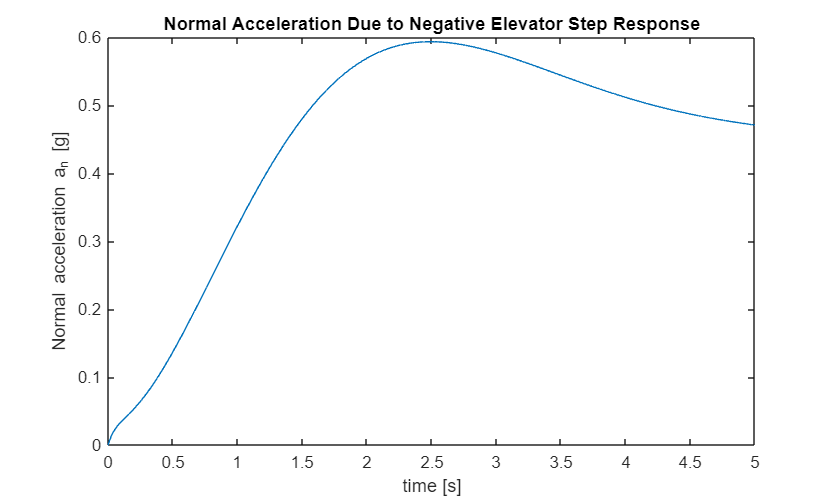

time_vector = 0:0.001:5;

[y,t] = step(-tf_an_de_minreal, time_vector);

plot(t, y)
xlabel("time [s]")
ylabel("Normal acceleration a_n [g]")
title("Normal Acceleration Due to Negative Elevator Step Response")
set(gcf,'units','points','position',[0,0, 500, 300])


figure;

**Zeros and Poles**

zero(tf_an_de_minreal)

ans =  -20.2000 + 0.0000i
 -20.2000 + 0.0000i
  -1.9412 + 5.5105i
  -1.9412 - 5.5105i
   0.0094 + 0.0000i
  -0.0059 + 0.0000i
   0.0000 + 0.0000i


pole(tf_an_de_minreal)

ans =  -20.1999 + 0.0000i
 -20.2001 + 0.0001i
 -20.2001 - 0.0001i
  -0.7621 + 1.2051i
  -0.7621 - 1.2051i
  -0.0039 + 0.0844i
  -0.0039 - 0.0844i
   0.0000 + 0.0000i


## Varying Accelerometer Position

fi_flag_Simulink = 0;
open_system("LIN_F16Block");

x_a_lst = [0, 5, 5.9, 6, 7, 15];
x_a_lst_meters = x_a_lst * 0.3048;

% Arrays to store transfer functions and step responses
tf_lst = cell(size(x_a_lst));
time_vector = 0:0.001:0.3;
zero_lst = cell(size(x_a_lst));

figure % Create a new figure

hold on;

for i = 1:length(x_a_lst)
    % Set the parameter value for x_a
    blockPath = ['LIN_F16Block/x_a'];
    set_param(blockPath, 'Value', num2str(x_a_lst_meters(i)));

    % Trim the model
    [trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_apa.velocity, fc_apa.altitude, FC_flag,18);
    trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;

    % Linearize model
    operating_point = operpoint('LIN_F16Block');
    operating_point.Inputs(1).u = trim_thrust_lin;
    operating_point.Inputs(2).u = trim_control_lin(1);
    operating_point.Inputs(3).u = trim_control_lin(2);
    operating_point.Inputs(4).u = trim_control_lin(3);

    SS_lo = linearize('LIN_F16Block');

    % Convert state-space to transfer function
    [tf_num, tf_den] = ss2tf(SS_lo.A, SS_lo.B, SS_lo.C, SS_lo.D, 2);
    tf_num = tf_num(19,:);
    tf_an_de = tf(tf_num, tf_den);
    tf_an_de_minreal = minreal(tf_an_de);

    % Save transfer function for later use
    tf_lst{i} = tf_an_de_minreal;

    % Save zeros
    zero_lst{i} = zero(tf_an_de_minreal);

    % Simulate the step response
    y = step(-tf_an_de_minreal, time_vector);

    % Plot the step response
    plot(time_vector, y, 'LineWidth', 1, 'DisplayName', ['x_a = ' num2str(x_a_lst(i))]);
end

Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = 4.2733e-15 deg
rud    = 3.6479e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = 4.2733e-15 deg
rud    = 3.6479e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = 4.2733e-15 deg
rud    = 3.6479e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = 4.2733e-15 deg
rud    = 3.6479e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = 4.2733e-15 deg
rud    = 3.6479e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2

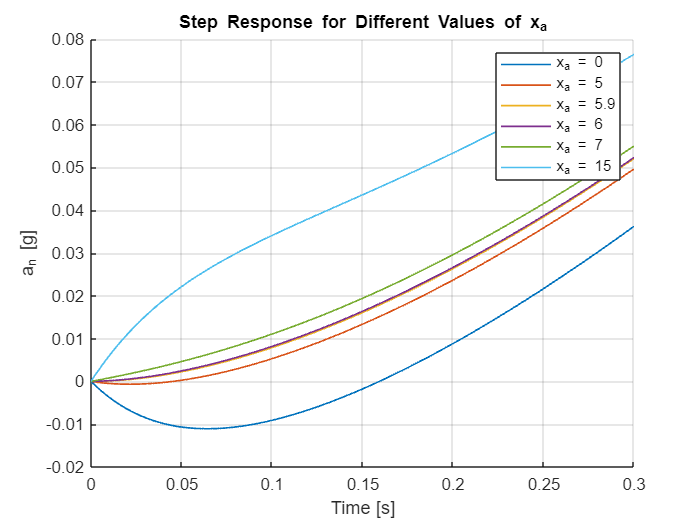


hold off;

xlabel('Time [s]');
ylabel('a_n [g]');
title('Step Response for Different Values of x_a');
legend('show');
grid on;


% Display zeros
for i = 1:length(x_a_lst)
    fprintf('Zeros for x_a = %f: %s\n', x_a_lst(i), mat2str(zero_lst{i}));
end

Zeros for x_a = 0.000000: [-20.2000003533792;-20.1999996466209;9.75967822856862;-5.39251395653553;0.0093895441977041;-0.00591863785833283;2.483174779347e-10]
Zeros for x_a = 5.000000: [40.6734209803364;-20.2+9.6055789156385e-08i;-20.2-9.6055789156385e-08i;-8.48733397723956;0.00938832134362296;-0.00591851096336736;6.53051903636958e-11]
Zeros for x_a = 5.900000: [-78920.0978385084;-20.2000035941049;-20.199996405894;-10.518608316099;0.00938810130179732;-0.00591848809784783;1.19193602209941e-11]
Zeros for x_a = 6.000000: [-283.718095197037;-20.200000684885;-20.199999315115;-10.8976525736431;0.00938807687034177;-0.00591848583351868;2.50390145007304e-10]
Zeros for x_a = 7.000000: [-13.7349248885237+9.67273525903474i;-13.7349248885237-9.67273525903474i;-20.2+8.76865734153149e-07i;-20.2-8.76865734153149e-07i;0.00938783242920219;-0.00591846028200725;5.73832703807276e-12]
Zeros for x_a = 15.000000: [-20.2000004594981;-20.1999995405019;-1.94118349335955+5.51047751382584i;-1.94118349335955-5.51047